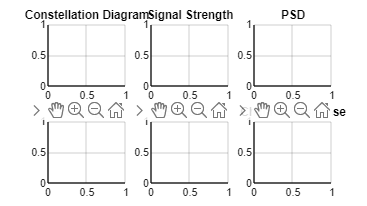

%% Wireless Voice Transmission System (IEEE 802.11a)
clear; close all;

% Parameters
Fs = 44100;          
distance = 10;       
txPower = 20;        
baseSensitivity = -85;   
chunkSize = 4410;    
numPaths = 3;        
symbolMapping = [-1-1i, -1+1i, 1-1i, 1+1i]/sqrt(2);

% Initialize plot data storage
BER_history = [];
time_history = [];

[x, Fs] = audioread('input.wav');
x = x(:);
totalErrors = 0;
totalBits = 0;
recAudioFull = [];

% Create and setup figures
fig = figure('Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);
subplot(2,3,1); hold on; grid on;
title('Constellation Diagram');
subplot(2,3,2); hold on; grid on;
title('Signal Strength');
subplot(2,3,3); hold on; grid on;
title('PSD');
subplot(2,3,4); hold on; grid on;
title('Eye Diagram');
subplot(2,3,5); hold on; grid on;
title('BER vs Time');
subplot(2,3,6); hold on; grid on;
title('Channel Response');


% Process in chunks
for chunk = 1:chunkSize:length(x)
    endIdx = min(chunk + chunkSize - 1, length(x));
    xChunk = x(chunk:endIdx);
    
    % Convert to binary
    binChunk = de2bi(typecast(single(xChunk), 'uint8'), 8);
    binChunk = binChunk(:);
    if mod(length(binChunk), 2) == 1
        binChunk = [binChunk; 0];
    end
    
    % QPSK Modulation
    dataSym = reshape(binChunk, 2, [])';
    dataSymIdx = bi2de(dataSym) + 1;
    modSignal = symbolMapping(dataSymIdx);
    
    % Channel effects
    rxSignal = zeros(size(modSignal));
    h = zeros(numPaths, 1);
    
    for path = 1:numPaths
        h(path) = (randn + 1i*randn)/sqrt(2);
        pathLoss = 20*log10(sqrt(distance^2 + path^2)) + 20*log10(5e9) - 147.55;
        shadow = 10^(8*randn(1,1)/20);
        pathGain = shadow * 10^(-pathLoss/20);
        rxSignal = rxSignal + pathGain * h(path) * modSignal;
    end
    
    % Add noise
    noiseVar = 10^(-90/10);
    noise = sqrt(noiseVar/2)*(randn(size(rxSignal)) + 1i*randn(size(rxSignal)));
    rxSignal = rxSignal + noise;
    
    % Receiver
    distances = zeros(length(rxSignal), length(symbolMapping));
    for i = 1:length(symbolMapping)
        distances(:,i) = abs(rxSignal - symbolMapping(i));
    end
    [~, detSymIdx] = min(distances, [], 2);
    detSym = de2bi(detSymIdx-1, 2);
    recBits = detSym(:);
    
    % Error calculation
    minLen = min(length(binChunk), length(recBits));
    totalErrors = totalErrors + sum(binChunk(1:minLen) ~= recBits(1:minLen));
    totalBits = totalBits + minLen;
    BER = totalErrors/totalBits;
    
    % Store BER history
    BER_history = [BER_history; BER];
    time_history = [time_history; chunk/Fs];
    
    % Audio reconstruction
    recBitsReshaped = reshape(recBits(1:floor(length(recBits)/8)*8), 8, [])';
    recBytes = uint8(bi2de(recBitsReshaped));
    recAudio = typecast(recBytes, 'single');
    recAudioFull = [recAudioFull; recAudio(:)];
    
    % Update plots every 1 second
    if mod(chunk, Fs) == 0
        figure(fig);
        
        % Constellation
        subplot(2,3,1); cla;
        plot(symbolMapping,'rx','MarkerSize',10,'LineWidth',2); 
        plot(rxSignal(1:min(100,end)),'.b','MarkerSize',4);
        xlabel('In-Phase'); ylabel('Quadrature');
        legend('Original','Received');
        
        % Signal Strength
        subplot(2,3,2); cla;
        plot(abs(rxSignal(1:min(100,end))));
        xlabel('Symbol Index'); ylabel('Magnitude');
        
        % PSD
        subplot(2,3,3); cla;
        periodogram(rxSignal,[],[],Fs,'centered');
        
        % Eye Diagram (simplified)
        subplot(2,3,4); cla;
        plotEye = reshape(real(rxSignal(1:floor(length(rxSignal)/2)*2)), 2, []);
        plot(plotEye);
        xlabel('Symbol Period'); ylabel('Amplitude');
        
        % BER Plot
        subplot(2,3,5); cla;
        plot(time_history, BER_history, 'b-');
        xlabel('Time (s)'); ylabel('BER');
        
        % Channel Response
        subplot(2,3,6); cla;
        stem(1:numPaths, abs(h));
        xlabel('Path Index'); ylabel('Magnitude');
        
        drawnow;
    end
end

% Final BER
fprintf('Final BER: %f\n', BER);

Final BER: 0.485186



% Save audio
audiowrite('output_3.wav', recAudioFull, Fs);